# 2022 F eksamen løsning

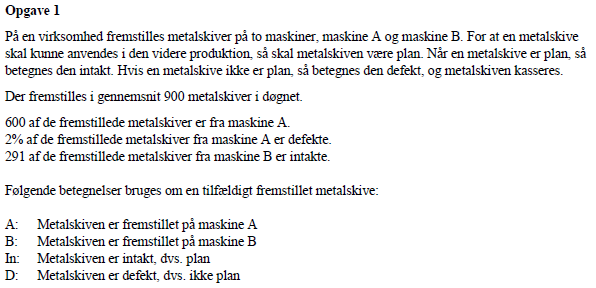

clc;clear;

n = 900 % total

n = 900


nA = 600

nA = 600

nB = n-nA

nB = 300


Adefekt = 0.02 * nA

Adefekt = 12

Aintakt = nA - Adefekt

Aintakt = 588


Bintakt = 291

Bintakt = 291

Bdefekt = nB - Bintakt

Bdefekt = 9


rownames = ["Intakt";"Defekt";"I alt"];
varnames = ["Maskine A","Maskine B","I alt"]

varnames = 1×3 string array
    "Maskine A"    "Maskine B"    "I alt"



disp(table([Aintakt;Adefekt;nA],[Bintakt;Bdefekt;nB], [Aintakt+Bintakt;Adefekt+Bdefekt;n],RowNames=rownames,VariableNames=varnames))

              Maskine A    Maskine B    I alt
              _________    _________    _____

    Intakt       588          291        879 
    Defekt        12            9         21 
    I alt        600          300        900 



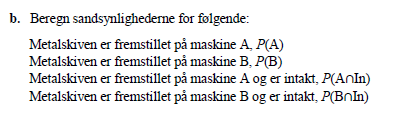

P_A = nA/n

P_A = 0.6667

P_B = nB/n

P_B = 0.3333

P_A_og_intakt = Aintakt/n

P_A_og_intakt = 0.6533

P_B_og_intakt = Bintakt/n

P_B_og_intakt = 0.3233

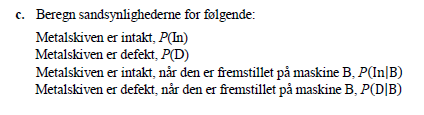

P_intakt = (Aintakt+Bintakt)/n

P_intakt = 0.9767

P_defekt = 1-P_intakt

P_defekt = 0.0233


P_intakt_givet_B = Bintakt/nB

P_intakt_givet_B = 0.9700

P_defekt_givet_B = 1 - P_intakt_givet_B

P_defekt_givet_B = 0.0300

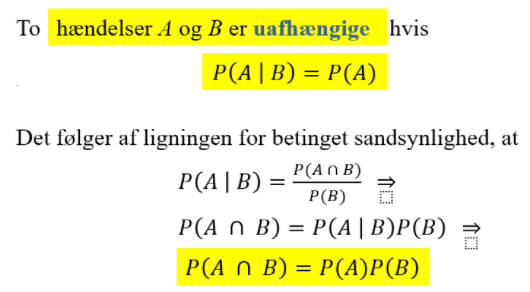

Hændelsen er uafhængig, hvis og kun hvis, c = P(In), hvilket ikke er tilfældet, eftersom 

P(In|B) = 0.9700

P(In) = 0.9767

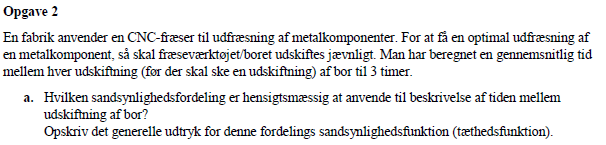

En poissonfordeling ville være hensigtsmæssig at bruge

lambda = 1/3

lambda = 0.3333

mu = 1/lambda

mu = 3

varians = 1/lambda^2

varians = 9

stdafv = 1/lambda

stdafv = 3

P_inden_for_2_timer = expcdf(2,mu)

P_inden_for_2_timer = 0.4866

P_mere_end_6_timer = 1 - expcdf(6,mu)

P_mere_end_6_timer = 0.1353

P_mellem_2_og_4_timer = 1 - expcdf(2,mu) - (1 - expcdf(4,mu))

P_mellem_2_og_4_timer = 0.2498

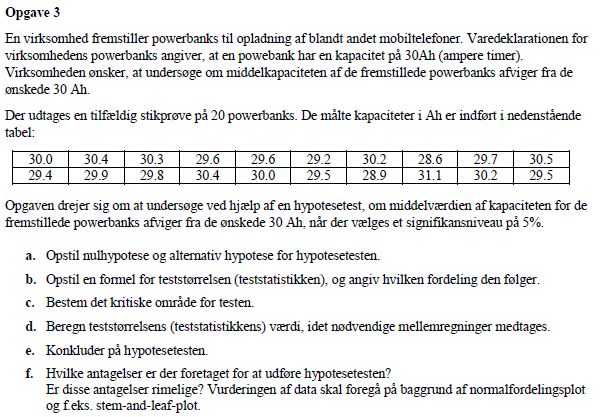

clc; clear;

data = importdata("Data_M4STI1_2022F.xlsx");
data = data.data(:,1)

data =    30.0000
   30.4000
   30.3000
   29.6000
   29.6000
   29.2000
   30.2000
   28.6000
   29.7000
   30.5000


## Nulhypotese

H0: $\mu = 30$Ah

Ha: $\mu \neq 30$Ah

Der er altså tale om en 2-sidet test på middelværdien, med et signifikansniveau på 5%

Herunder er der benyttet en funktion, jeg selv har skrevet (kode nederst i dokumentet samt afleveret som MatLab fil med eksamensopgaven), der beregner og plotter hypotesetesten. 

Det vil sige, at opgave b-e tages i ét hug.

Der laves en Students t-test, eftersom der kun er 20 datapunkter at teste ud fra, hvor man typisk ville antage at dataet er normalfordelt, skulle der have været mere end 30 datapunkter.

ans = -1.2170

Stikprøvemiddelværdiens formel


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

-----------------------------------------------------------------
Stikprøvevariansens formel


$$s=\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}$$

-----------------------------------------------------------------
Stikprøvestandardafvigelsens formel


$$s=\sqrt{\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}}$$

-----------------------------------------------------------------
t-værdiens formel


$$\frac{t_{\mathrm{df},\alpha }}{2}=\mathrm{tinv}\,\left(\frac{\alpha }{2}\,n-1\right)$$

-----------------------------------------------------------------
Teststørrelsens formel


$$t=\frac{\bar{y}-\mu_{0}}{s\,\sqrt{n}}$$

----------------------------------------------------------------------------------------------
    Datanavn    Middelværdi    Varians    Standardafv.    Datapunkter
      navn                                                           
    ________    ___________    _______    ____________    ___________

    {'data'}       29.84        0.346        0.588            20     

    Frihedsgrader    Nedre grænse    Øvre grænse    Teststatistikken    p-værdi    h-værdi
    _____________    ____________    ___________    ________________    _______    _______

         19             -2.093          2.093    

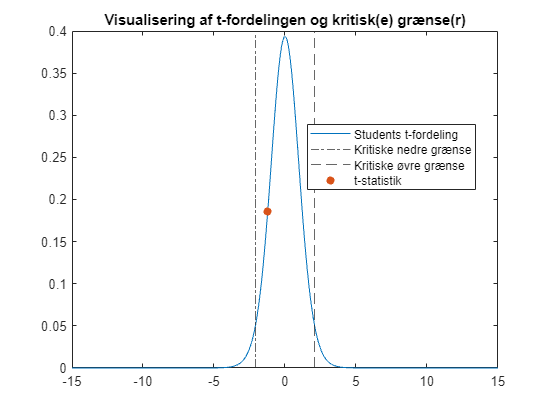

Da h = 0 forkastes nulhypotesen ikke
Ydermere ses det også at t-værdien -1.217 ikke overstiger den kritiske grænse på -2.093


H0 = 30;

StudentTestMiddel(data,H0,"both",95)

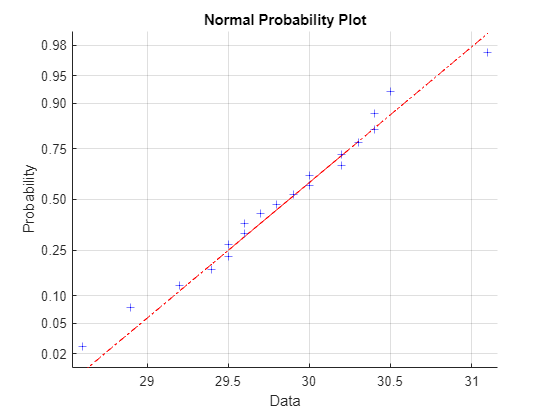

normplot(data)


stemleafplot(data,0)

  2 | 9 9 9 9
  3 | 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 1
key: 36|5 = 365
stem unit: 10
leaf unit: 1


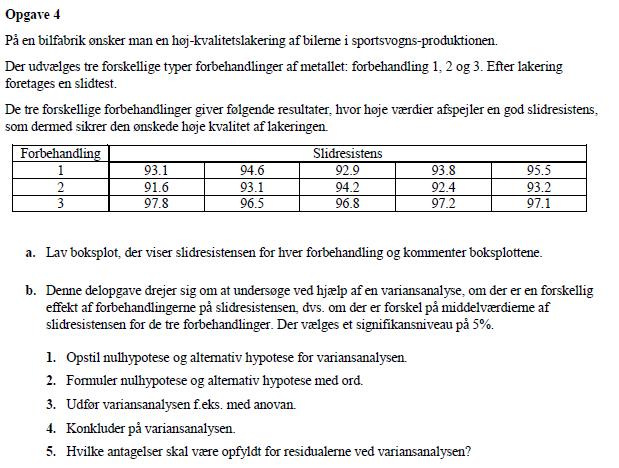

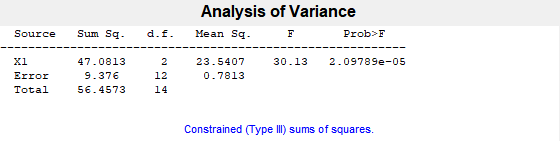

clc; clear;

data = importdata("Data_M4STI1_2022F.xlsx");
data_group = data.data(:,5);
data_slid = data.data(:,6);

[p, table, stats] = anovan(data_slid, data_group);